# Image Clustring

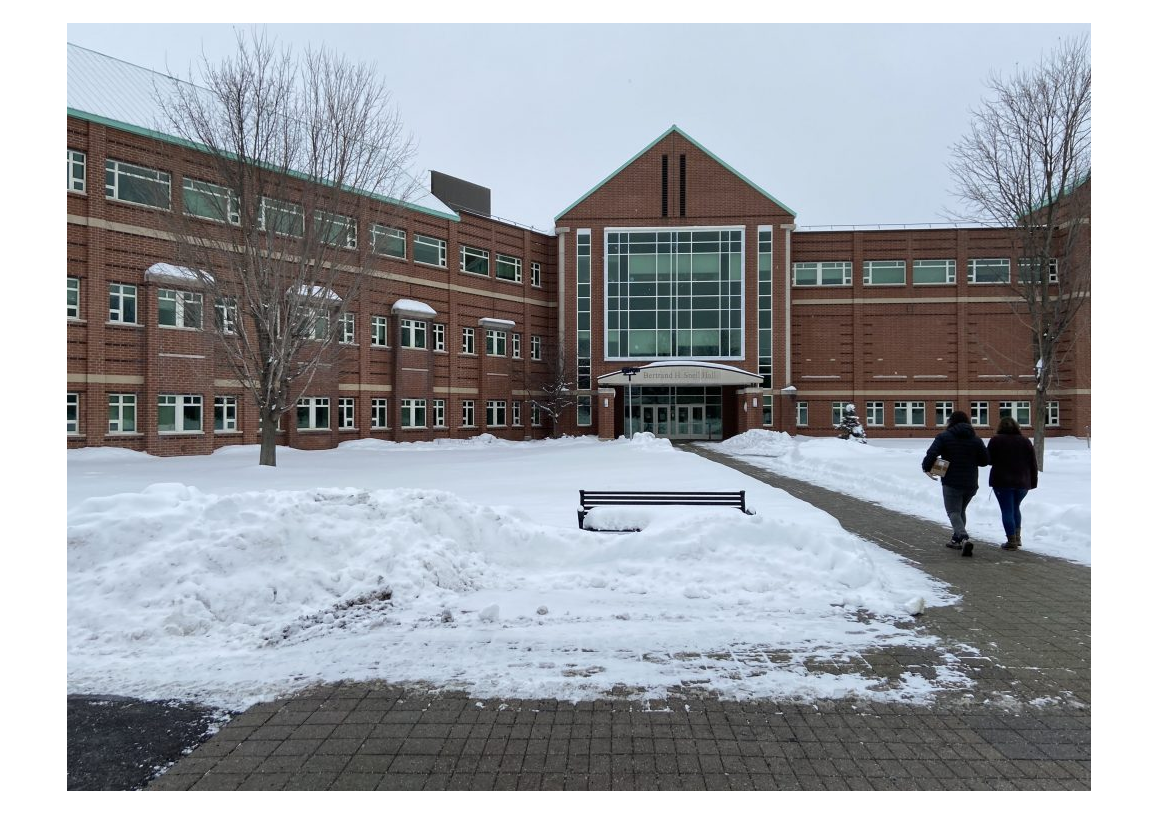

clearvars; close all; clc;

I = imread('CU.jpeg');
imshow(I)

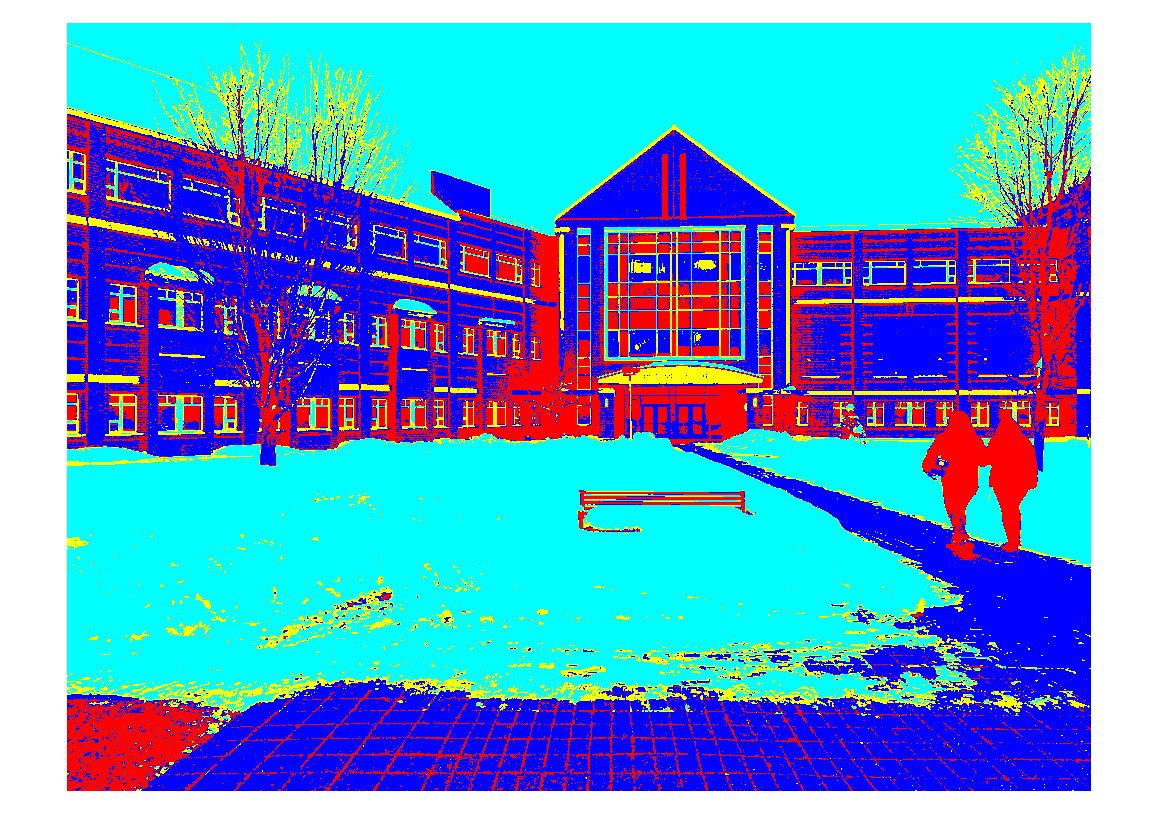

% make sure your image is in double data type so that you can make
% mathematical operations on it

D = im2double(I);

[m,n,c] = size(D); % # of [rows, columns, color]
% Reshape your image and make it a three columns where each column has a
% single color channel

D = reshape(D,m*n,c);


% Assume we chose K = 4 (number of clusters)
K= 4;

% now you call the kmeans
[L, mu] = kmeans(D,K);

% L now has labels that indicate the cluster index of each pixle
% mu has the centroid of each cluster

%Reshape the label as 2D image
L = reshape(L,m,n);

% you can plot the labeled image as:
imshow(label2rgb(L))
% you can choose the color map
colormap hot

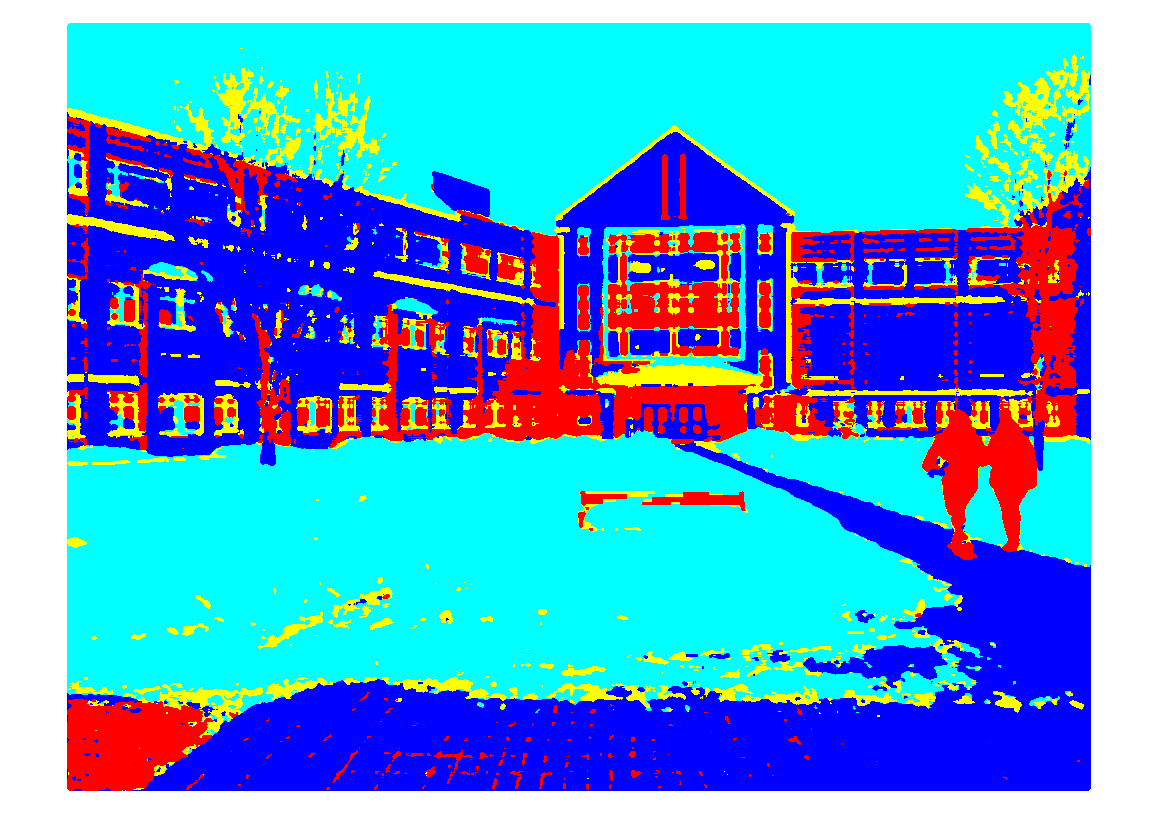



% you can apply filter to get more clear results
Lf1 = medfilt2(L,[5 5]);

imshow(label2rgb(Lf1))

% Other types of filters also may be used. Try some of the following.

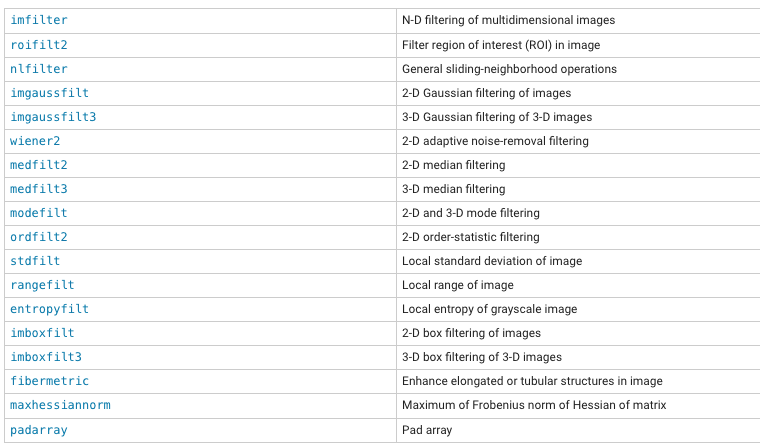

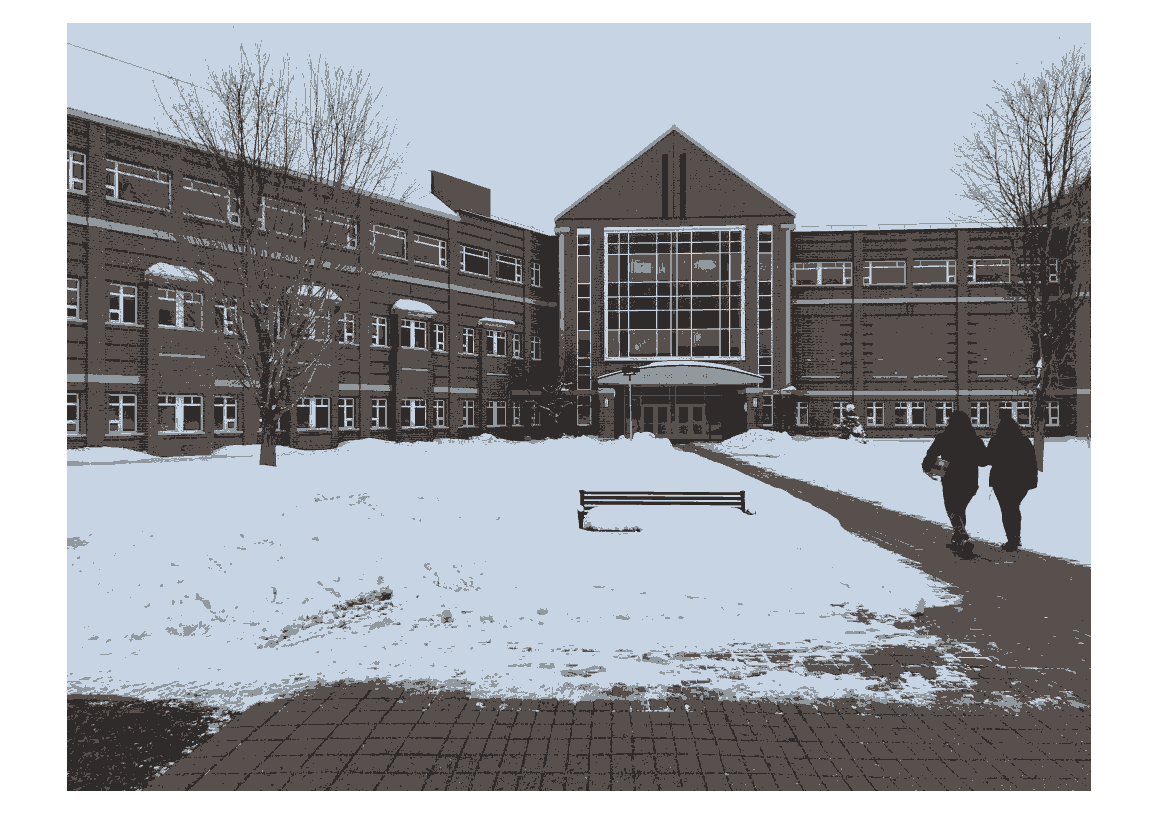

% Another way to see the clustered image, is by replaceing each pixle by
% the centroid of its cluster:

M = mu(L(:),:);

M = reshape(M,m,n,c);

imshow(M)

# Combining the spatial difference with color

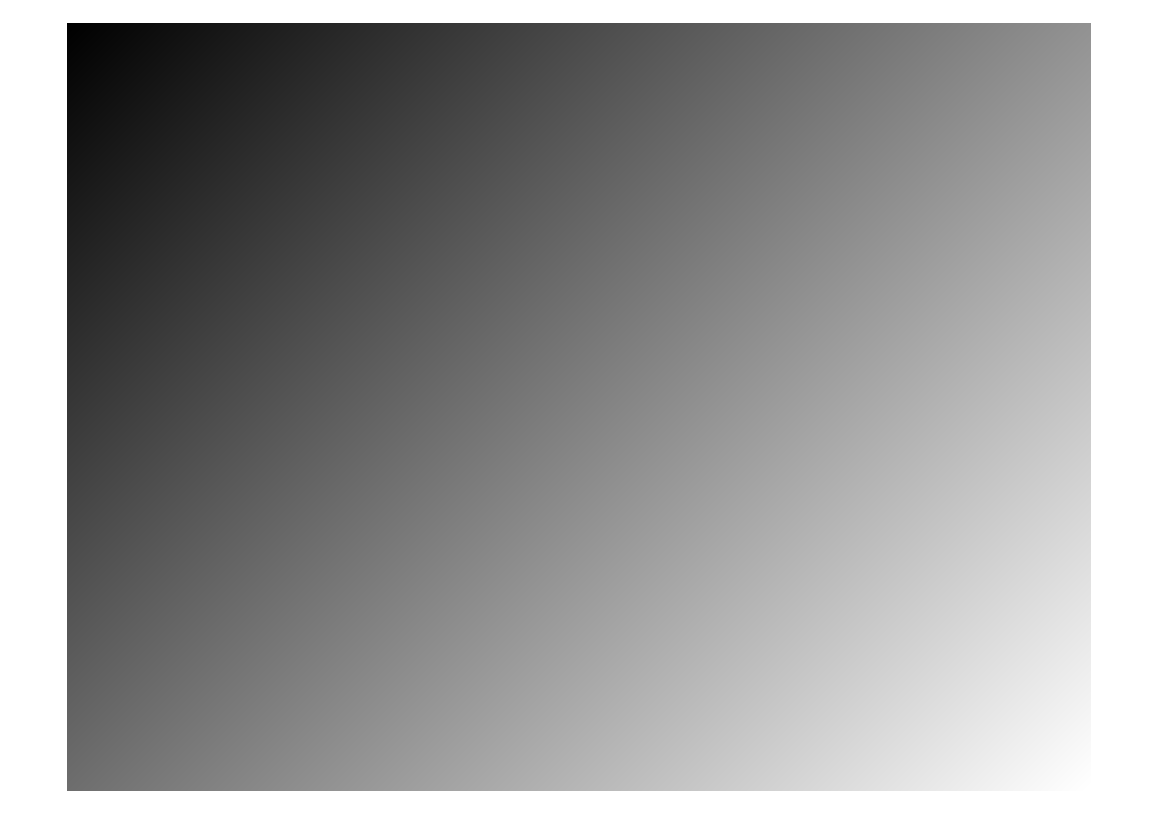

% you can generate a spatial difference image and add it to the clustring
% in each pixle you can store the distance from some reference pixle, say
% [1,1]

[sc,sr] = meshgrid(1:n,1:m);
S = [sr(:), sc(:)];
S = sum(S,2);
S = S./max(S); %normalize
S = reshape(S,m,n);
imshow(S) %show the distance variable

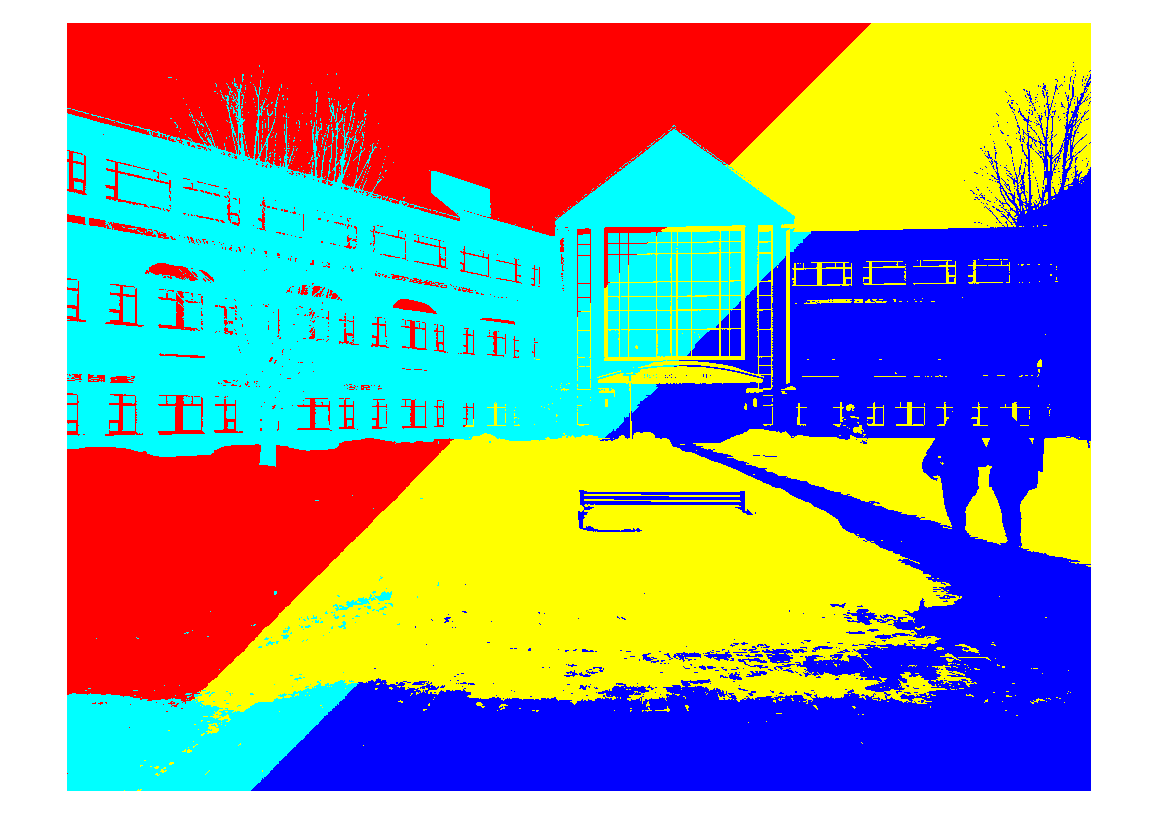



%Now we cluster the image with considering the spatial difference
%You can also decice a weight between color and distance
alpha = 0.75;
[L, mu] = kmeans([(1-alpha)*D, alpha*S(:)],K);

%Reshape the label as 2D image
L = reshape(L,m,n);

% you can plot the labeled image as:
imshow(label2rgb(L))
% you can choose the color map
colormap hot


% A better approch is to use large number of clusters and analyze their
% simlarity in different method
K = 20;
[L, mu] = kmeans([(1-alpha)*D, alpha*S(:)],K);

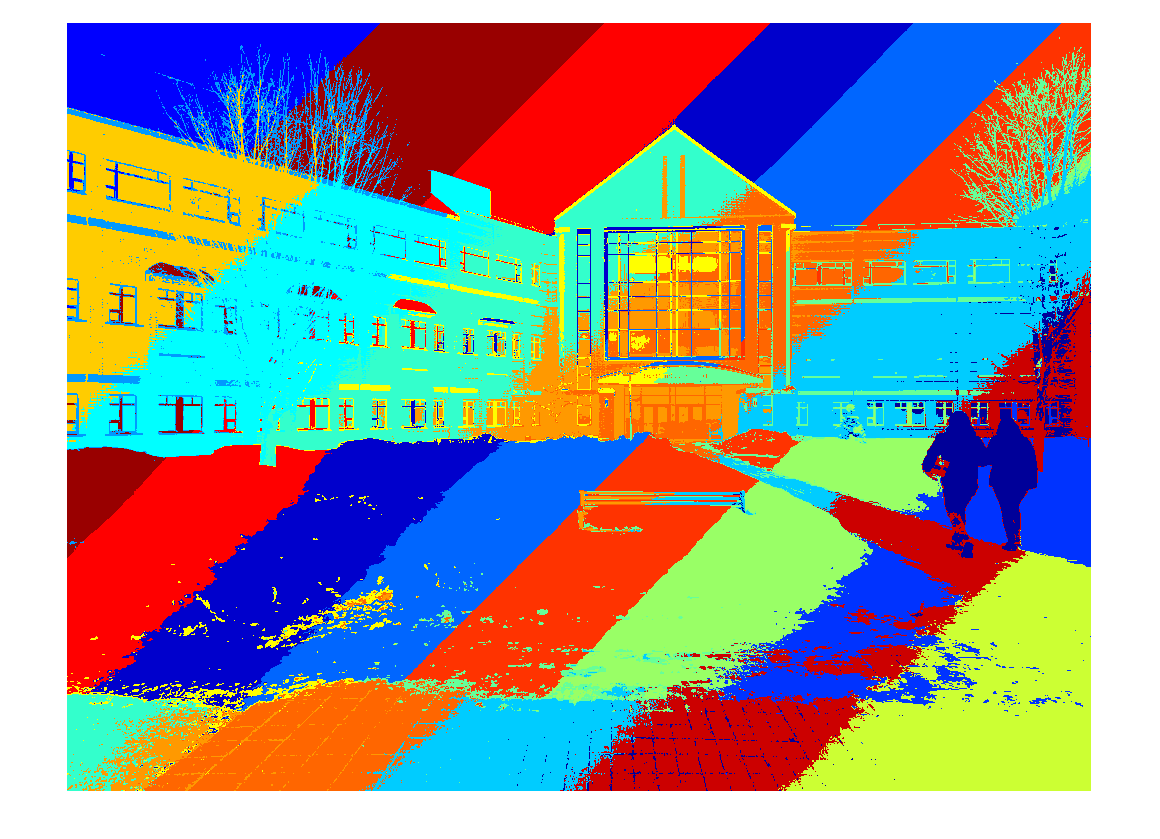


%Reshape the label as 2D image
L = reshape(L,m,n);

% you can plot the labeled image as:
imshow(label2rgb(L))